# Airframe Model - Altitude-Only Hover Model and Feed-Forward Control

## Topic

This LiveScript continues with the development of your lesson on Airframes and includes the introduction a simple model for hovering your UAV at a given altitude.

## Motivation

## Learning Objective

In this lesson you will develop a simple one-degree-of-freedom model for altitude control so that you can begin to model the first key element of UAV flight- Hovering.   You will write determine the forces necessary for hovering with motion limited to changes in altitude and you will incorporate those findings into a feed-forward control force. 

## Lesson

### Utilities Used in Lesson

clear;
addpath('utils');
params=sys_params;
m=params.mass;


### Hovering

In this module you will investigate adding a force to make your vehicle hover.  That is, maintain a steady position.    Eventually, you will do this want to command the vehicle to a position and then maintain it, but for this lesson, you can assume the vehicle is already at the desired position.   How do you set the paramters to achieve a hover state?   

#### Hover Example Code:

The code below models a UAV starting at rest at a prescribed position.   Modify the code and see and see if you can determine the force that is required to hover the UAV at a given altitude.   The UAV is hovering when its position does not change and its velocity is zero.

$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack +\frac{1}{m}\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
-\textrm{mg}
\end{array}\right\rbrack -k_d \sqrt{{\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
0\\
0\\
0\\
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
F_{\textrm{hover},x} \\
F_{\textrm{hover},y} \\
F_{\textrm{hover},z} 
\end{array}\right\rbrack \right\rbrace$   with $\left\lbrack \begin{array}{c}
x\left(0\right)\\
y\left(0\right)\\
z\left(0\right)\\
v_x \left(0\right)\\
v_y \left(0\right)\\
v_z \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 \\
v_{\textrm{x0}} \\
v_{\textrm{y0}} \\
v_{\textrm{z0}} 
\end{array}\right\rbrack$

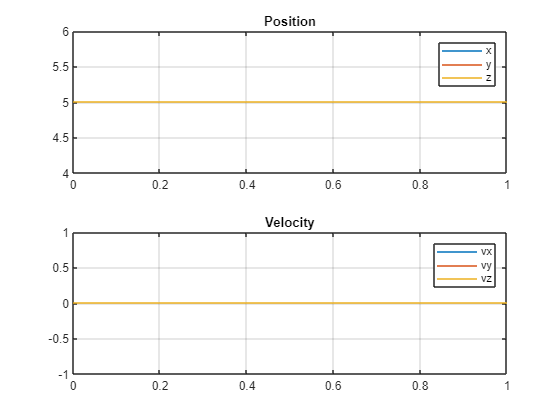

% Code Provided

initial_x = 5;
initial_y = 5;
initial_z = 5;

v0= 0;    % m/s
thetad=0;
phid=0;

Hover_Acceleration_x = 0;
Hover_Acceleration_y = 0;
Hover_Acceleration_z = -9.81;

F_hover=m*[Hover_Acceleration_x ; Hover_Acceleration_y; Hover_Acceleration_z];


tmax = 1; 
tspan=[0,tmax];

theta=thetad*pi/180;  phi=phid*pi/180;                                 

X0=[initial_x;initial_y;initial_z]; V0=[v0*sin(theta)*cos(phi);v0*sin(theta)*sin(phi);v0*cos(theta)];

% % Solve using ODE45
[~,fxyz,mxyz,kd,zdesired,kp,kv,ff]=initializeParameters;

w0=[X0;V0;zeros(6,1)];
systemDerivative=@(t,w)dwdt(t,w,mxyz,F_hover,kd,ff,kp,kv,zdesired);
[ts,ws]=ode45(systemDerivative,tspan,w0); 
parametric_output3dof(ts,ws)

#### Findings

By experimenting with all of the parameters, you probably are beginning to realize a few things.   To make your vehicle hover in place by applying a constant force $F_{\textrm{hover}}$ the following is true:

- Initial position $\left(x_0 \;,y_0 \;,z_0 \right)$, does not matter.

- Initial velocity $v_0$ needs to be zero

- $F_{\textrm{hover}}$ must be precisely defined to be $F_{\textrm{hover}} =\left\lbrack \begin{array}{c}
0\\
0\\
+\textrm{mg}
\end{array}\right\rbrack$

With some reflection, this does not come as a surprise.    If the force $F_{\textrm{hover}}$ is of equal magnitude to the gravitational force and in the opposite direction, and there is no velocity, hence no drag force, then there are no forces acting on the vehicle at all.   In this case its momentum will remain constant, and if its velocity is zero, then that means the vehicle is staying in place.

### Feed Forward

This special case of achieving a UAV that successfully hovers is extremely important.    Most of the schemes by which you will control the motion of the UAV are derived by looking at perturbations to this configuration.  You discovered that if the drone is level, so that the the forces exerted by the propellers are parallel to the z-axis in the Inertial frame of reference, then the thrust force that is required to hover is that which precisely compensates for gravity.  As you determined in the section above, this comes as no surprise.   Since it is so important, we will use it as a "feed forward" term in the controller.  That is to say, we will always a force in our vehicle that balances gravity.    This means there is a nominal speed our propellers will spin.  If we want the vehicle to go up, we will increase the propeller speed from this nominal value.  If we want our vehicle to go down, we will decrease the propeller speed from this nominal value.

We will call this force a*** feed-forward ***control and we will talk about that more when we discuss the control system at length.  For now just remember that

$F_{\textrm{fwd}} =\textrm{mg}$ and that our equations become:

$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack +\frac{1}{m}\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
-\textrm{mg}
\end{array}\right\rbrack -k_d \sqrt{{\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
0\\
0\\
0\\
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
F_{\textrm{fwd}} 
\end{array}\right\rbrack \right\rbrace$   with $\left\lbrack \begin{array}{c}
x\left(0\right)\\
y\left(0\right)\\
z\left(0\right)\\
v_x \left(0\right)\\
v_y \left(0\right)\\
v_z \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 \\
v_{\textrm{x0}} \\
v_{\textrm{y0}} \\
v_{\textrm{z0}} 
\end{array}\right\rbrack$

## Conclusion

In this module you determined the force that was necessary to counteract the environmental forces (i.e. gravity) and enable your UAV to hover at a position assuming your UAV was level to the ground and therefore perpendicular to the gravity vector.   You introduced a applied force, the feed-forward force, into your system, so that any additional applied forces are those that moves the UAV from its hovering position to another position. 

## Exercise

Write a new function for $\frac{\mathrm{d}}{\mathrm{d}t}Z\left(t\right)=F\left(t,Z\right)$  which includes a feed-forward term as discussed here.    As above, it will be convenient to write it in a form like

% Your code goes here


